|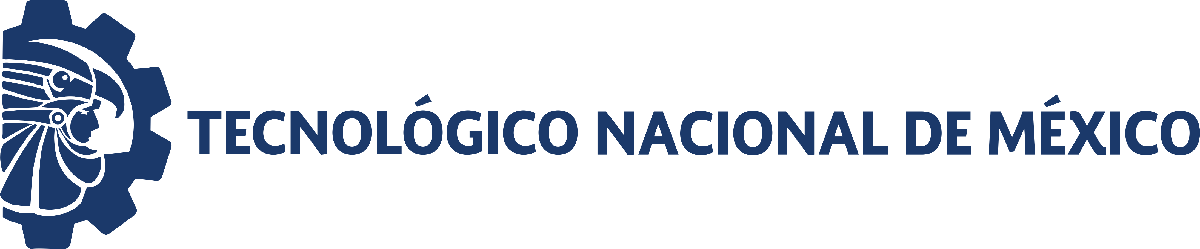                                 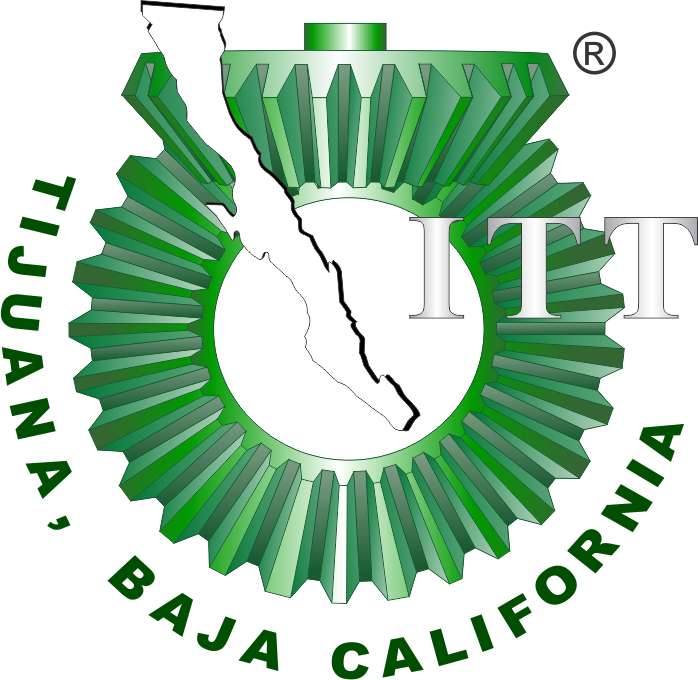

# Práctica 3: Sistema Cardiovascular 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[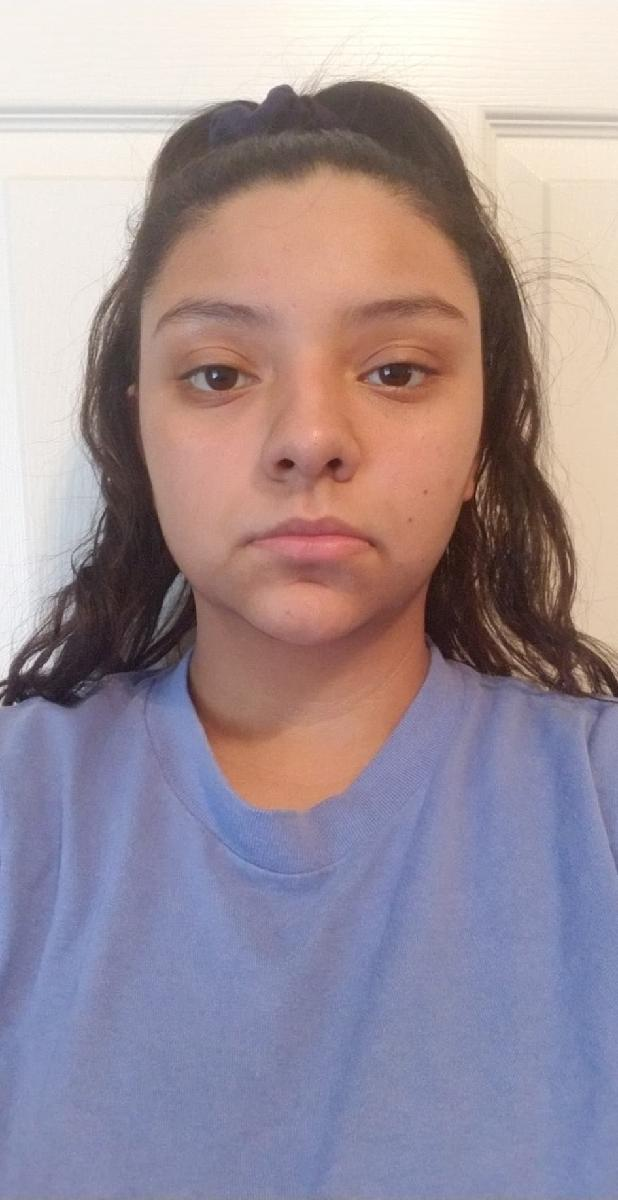]

Nombre del alumno: Jael Badillo Cruz 

Número de control: 22210409

Correo institucional:l22210409@tectijuana.edu.mx

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
parameters.StopTime = tend;
parameters.Solver = 'ode15';
parameters.MaxStep = '1E-3';
Controlador = 'PI';

## Lazo Abierto

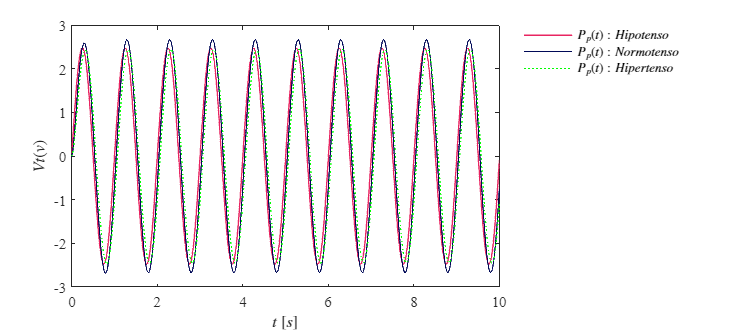

file = 'PRACTICA3';
open_system(file);
x = sim(file,parameters);
opt = 1;
lazoabierto(x.t,x.Ppx,x.Ppy,x.Ppz,opt);

## Hipertenso

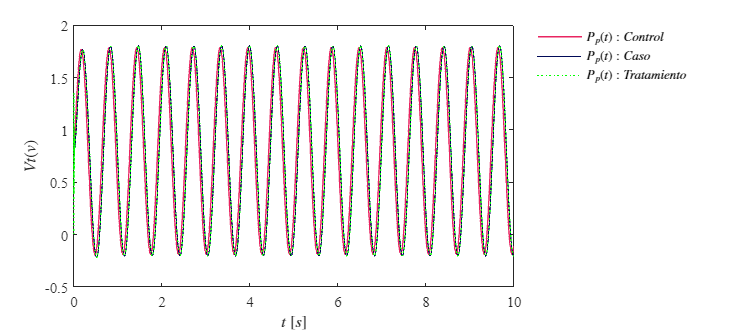

file = "Hipertensooo";
open_system(file);
x= sim(file,parameters);
opt= 2;
plotsignals(x.t,x.Ppx,x.Ppy,x.Ppz,opt);

## Hipotenso

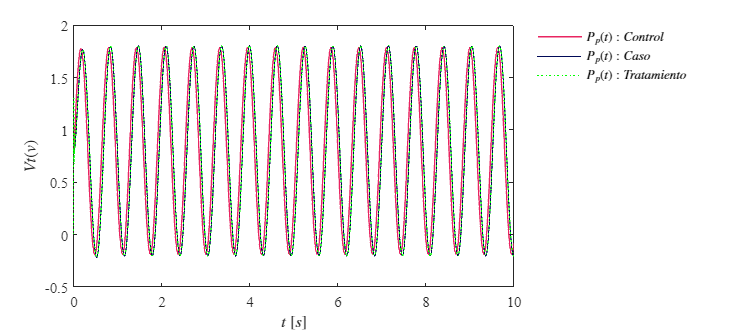

file = "Hipotenso22";
open_system(file);
x= sim(file,parameters);
opt= 3;
plotsignals(x.t,x.Ppx,x.Ppy,x.Ppz,opt);

## Funcion:Respuesta a las señales

function lazoabierto(t,Ppx,Ppy,Ppz,opt)
set(figure(),'Color','w')
set(gcf,'Units','Centimeters','Position',[1,1,18,8])
set(gca,'FontName','Times New Roman')
fontsize(10,'points')
red = [232/255, 37/255,97/255];
blueR = [0, 9/255, 87/255];
green = [0, 255/255, 0];
hold on; grid off; box on;

 plot(t, Ppx, 'LineWidth', 1, 'Color', red)
 plot(t, Ppy, '-','LineWidth', 0.5, 'Color', blueR)
 plot(t, Ppz, ':', 'LineWidth', 0.5, 'Color', green)

 xlabel('$t$ $[s]$','Interpreter','Latex')
 ylabel('$Vt(v)$', 'Interpreter','Latex')


L= legend('$P_{p}(t):Hipotenso$','$P_{p}(t):Normotenso$','$P_{p}(t):Hipertenso$');
set(L, 'Interpreter','Latex','Location','northeastoutside','Box','off')

end

function plotsignals(t,Ppx,Ppy,Ppz,opt)
set(figure(),'Color','w')
set(gcf,'Units','Centimeters','Position',[1,1,18,8])
set(gca,'FontName','Times New Roman')
fontsize(10,'points')
red = [232/255, 37/255,97/255];
blueR = [0, 9/255, 87/255];
green = [0, 255/255, 0];
hold on; grid off; box on;

 plot(t, Ppx, 'LineWidth', 1, 'Color', red)
 plot(t, Ppy, '-','LineWidth', 0.5, 'Color', blueR)
 plot(t, Ppz, ':', 'LineWidth', 0.5, 'Color', green)

 xlabel('$t$ $[s]$','Interpreter','Latex')
 ylabel('$Vt(v)$', 'Interpreter','Latex')


L= legend('$P_{p}(t):Control$','$P_{p}(t):Caso$','$P_{p}(t):Tratamiento$');
set(L, 'Interpreter','Latex','Location','northeastoutside','Box','off')
end